# **TASK_01:**    Parameters for the Equilibrium of a 3 Force Body system

Consider the system shown below.  We have a quadrilateral steel plate suspended from a support frame.  The steel plate is acted on by two spring tensions $F_{1\;} \;,F_2$, and its own weight $W$.  The points of application of these three forces are at the centres of the holes A and B and at the body’s centre of mass G, as shown in the figure below. The system is planar, that is all forces lie in one plane.

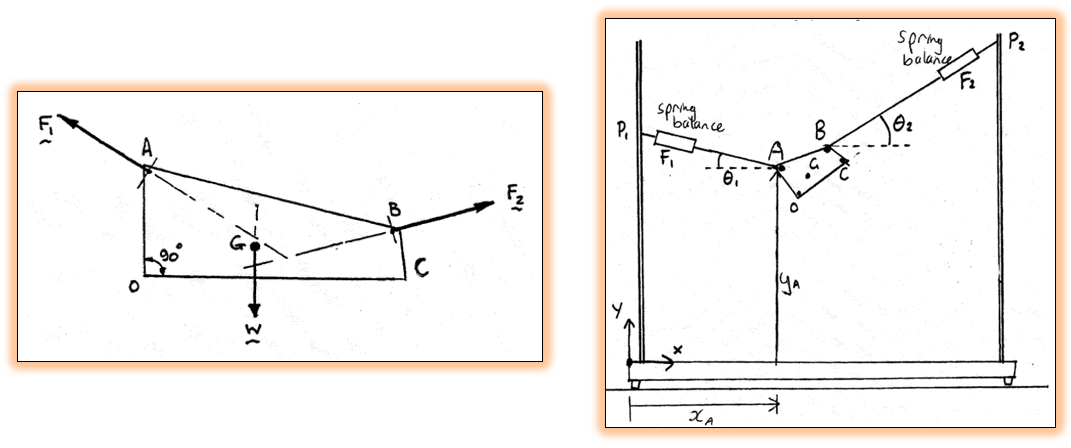

## Overview:

- In this script, we'll create MATLAB variables that will be used by our Simulink model of this apparatus.

- These model variables will be defined in the BASE MATLAB workspace

## Instructions:

First Run this script  ... and then review it's contents

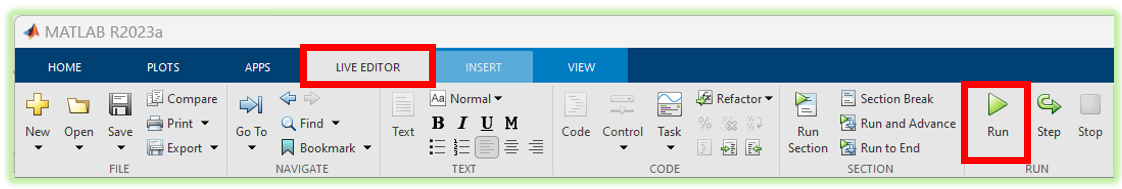

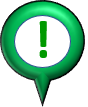 **NOTE:**  

- Our model has dozens of parameters, but there are (probably) only a few that you want to play with. We've signposted these parameters by attaching them to interactive** slider bars**.  

- When you interact with these **slider bars**, the script will "rerun" that section automatically and your BASE workspace will have the new parameter values.

## Start with a clean slate:

Let's delete any variables that may already be in your BASE workspace

clear

# Define our Model parameters - the Tunable parameters

Our model has dozens of parameters, but here are the main parameters that you can ***tune*** while exploring this experiment

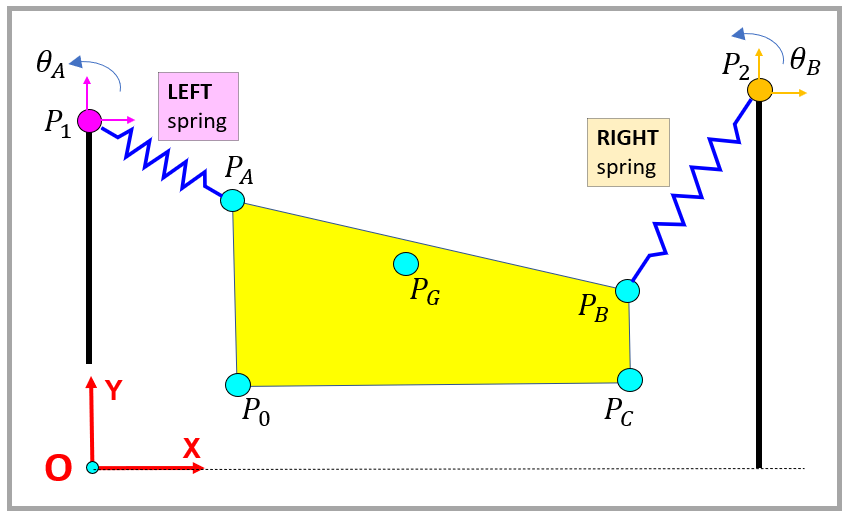     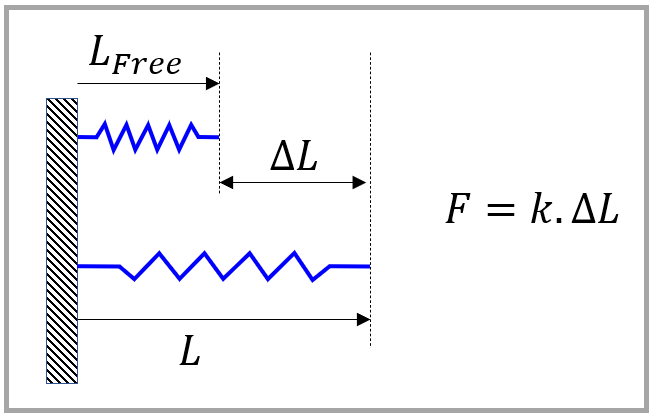

### Steel plate parameters

- The mass of the plate

- The initial $\left(x,y\right)$ position of point $P_0$ relative to the red INERTIAL frame

TUNE.mass_plate        = 2; % (kg)
TUNE.P0_X_rel_inertial = 0.3; % (m)
TUNE.P0_Y_rel_inertial = 0.1; % (m)

### Support Frame parameters

- The $\mathit{\mathbf{Y}}$ ***co-ordinates*** of the Frame attachment points $P_1 \;,P_2$

TUNE.P1_Y_rel_inertial = 1.3; % (m)
TUNE.P2_Y_rel_inertial = 1.3; % (m)

### Spring parameters

- The stiffness, damping and unstretched (aka free) length

TUNE.Spring_stiffness      =  25; % (N/m)
TUNE.Spring_damping        =  1.5; % (N.s/m)
TUNE.Spring_free_length    =  0.42;                 % (m)

# Define our Model parameters - the Dependent parameters

Next, let's define some parameters that charaterise our steel plate

### Define the steel plate:

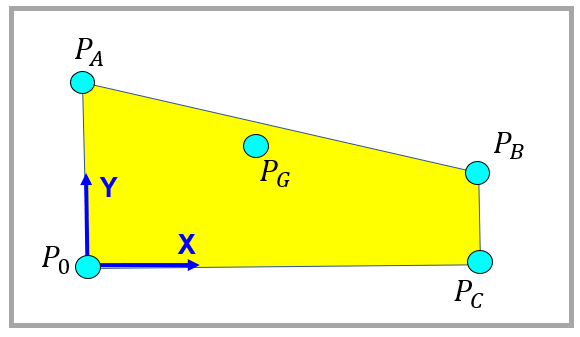

Define the $\left(x,y\right)$ co-ordinates of the 4 corners of the plate, ***relative to the BODY FIXED frame*** at point $P_0$. Define them in the order:

- 
$$P_0 \;\;,\;P_C \;\;,\;P_B \;\;,\;P_A$$


                    % P0,  PC,   PB,    PA
tmp_plate_X_points  = [0,  0.3,  0.3,   0   ]';  % (m)
tmp_plate_Y_points  = [0,  0,    0.05,  0.2 ]';  % (m)
% tmp_plate_X_points  = [0,  0.3,  0.5,   0   ]';  % (m)
% tmp_plate_Y_points  = [0,  0,    0.05,  0.4 ]';  % (m)

quad_obj            = bh_quadshape_CLS( tmp_plate_X_points, ...
                                        tmp_plate_Y_points);

% do a little bit of a tidy up
clear tmp_plate_X_points  tmp_plate_Y_points

Define the plate's thickness

quad_obj.z_thick = 0.01;   % (m)

Define the plate's **Mass**

quad_obj.mass    = TUNE.mass_plate  % (kg)

quad_obj =   bh_quadshape_CLS with properties:

              x_col: [4×1 double]
              y_col: [4×1 double]
            z_thick: 0.0100
               mass: 2
                  P: [1×1 polyshape]
    xy_cent_rel2_11: [0.1200 0.0700]
             volume: 3.7500e-04
            density: 5.3333e+03
               area: 0.0375
                 P0: [0 0]
                 PA: [0 0.2000]
                 PB: [0.3000 0.0500]
                 PC: [0.3000 0]
                 PG: [0.1200 0.0700]


Plot the plate and show the location of it's **Center of Mass** (CoM)

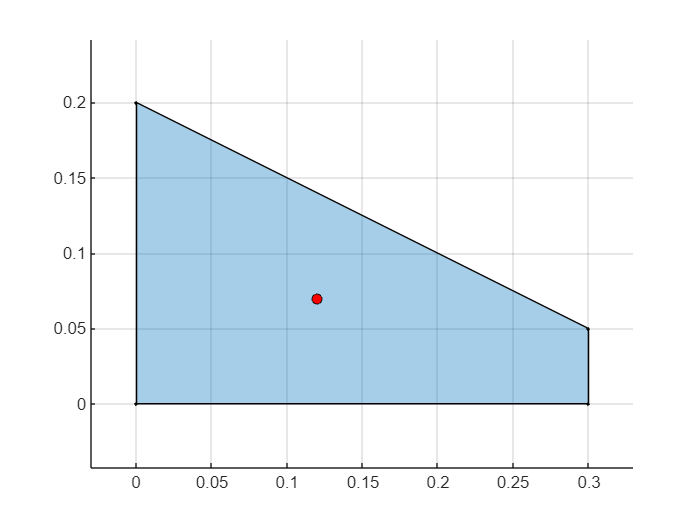

quad_obj.plot()

quad_obj

quad_obj =   bh_quadshape_CLS with properties:

              x_col: [4×1 double]
              y_col: [4×1 double]
            z_thick: 0.0100
               mass: 2
                  P: [1×1 polyshape]
    xy_cent_rel2_11: [0.1200 0.0700]
             volume: 3.7500e-04
            density: 5.3333e+03
               area: 0.0375
                 P0: [0 0]
                 PA: [0 0.2000]
                 PB: [0.3000 0.0500]
                 PC: [0.3000 0]
                 PG: [0.1200 0.0700]


### Define the SUPPORT FRAME attachment points relative to the ORIGIN of the inertial reference frame:

Define the $\left(x,y\right)$ co-ordinates of the Points $P_0 \;\;,P_1$ and $P_2$ ALL ***relative to the red INERTIAL frame***.

Points.P1 = [0, TUNE.P1_Y_rel_inertial];
Points.P2 = [1, TUNE.P2_Y_rel_inertial];
Points.P0 = [TUNE.P0_X_rel_inertial,  TUNE.P0_Y_rel_inertial];

### Define the INITIAL inertial positions of  points on the steel plate

Define the $\left(x,y\right)$ co-ordinates of the Points $P_A \;\;,P_B \;,{\;P}_C$ and $P_G$ ALL according to the RED INERTIAL frame.

Points.PA = Points.P0  +  quad_obj.PA;
Points.PB = Points.P0  +  quad_obj.PB;
Points.PC = Points.P0  +  quad_obj.PC;
Points.PG = Points.P0  +  quad_obj.PG;

[Theta.A_deg, Theta.B_deg] = LOC_calc_init_angs_deg(Points, quad_obj)

Theta = struct with fields:
    A_deg: -73.3008
    B_deg: -109.1790


Theta = struct with fields:
    A_deg: -73.3008
    B_deg: -109.1790


### Define the spring properties

Springs.LEFT.stiffness      = TUNE.Spring_stiffness;    % (N/m)
Springs.LEFT.damping        = TUNE.Spring_damping;      % (N.s/m)
Springs.LEFT.free_length    = TUNE.Spring_free_length;  % (m)
Springs.LEFT.initial_length = norm(Points.PA-Points.P1);

display(Springs.LEFT)

  struct with fields:

         stiffness: 25
           damping: 1.5000
       free_length: 0.4200
    initial_length: 1.0440




Springs.RIGHT.stiffness      = TUNE.Spring_stiffness;    % (N/m)
Springs.RIGHT.damping        = TUNE.Spring_damping;      % (N.s/m)
Springs.RIGHT.free_length    = TUNE.Spring_free_length;
Springs.RIGHT.initial_length = norm(Points.PB-Points.P2);

display(Springs.RIGHT)

  struct with fields:

         stiffness: 25
           damping: 1.5000
       free_length: 0.4200
    initial_length: 1.2176



And some lengths to "partially" visualise the springs

Springs.LEFT.visual_length  = Springs.LEFT.free_length  / 1;
Springs.LEFT.visual_R       = Springs.LEFT.visual_length  / 45;

Springs.RIGHT.visual_length = Springs.LEFT.free_length  / 1;
Springs.RIGHT.visual_R      = Springs.LEFT.visual_length  / 45;

### Define some parameters for the SUPPORT FRAME

Support.VERT.Len_X = 0.02;
Support.VERT.Len_Y = 1.25 * max([Points.P1(2), Points.P2(2)]);
Support.VERT.Len_Z = 0.02;
Support.VERT.dims  = [Support.VERT.Len_X, Support.VERT.Len_Y, Support.VERT.Len_Z];

Support.HORZ.Len_X = Points.P2(1) - Points.P1(1);
Support.HORZ.Len_Y = 0.02;
Support.HORZ.Len_Z = 0.02;
Support.HORZ.dims  = [Support.HORZ.Len_X, Support.HORZ.Len_Y, Support.HORZ.Len_Z];

### Define the gravitational aceleration constant

env.g = 9.80665;  % (m/s^2)

# Next Steps:

Our next step is to simulate a Simulink model of the 3 force Body system.  

- Please open the script file [`TASK_02_explore_the_model.mlx`](matlab:  edit TASK_02_explore_the_model) for instructions on how to do this.

# Local Subfunctions only beyond this point

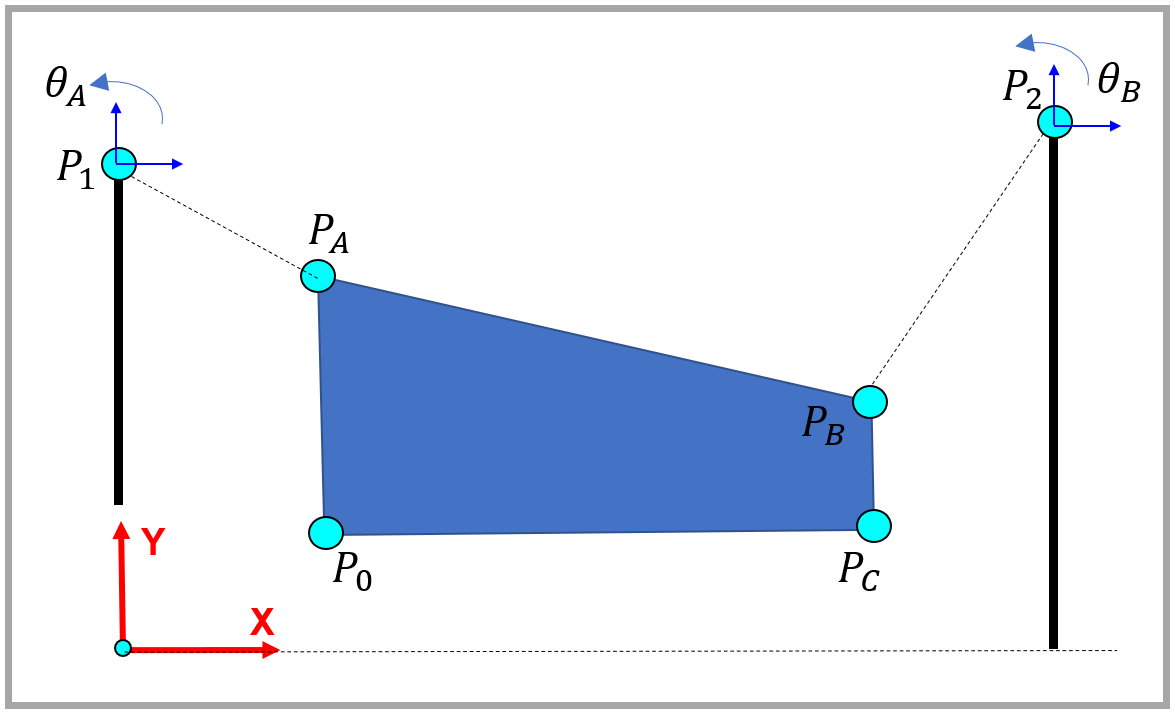

function [theta_A_deg,  theta_B_deg] = LOC_calc_init_angs_deg(Points, quad_obj)

    origin_1 = Points.P1;
    vec_A    = Points.PA - origin_1;
    
    origin_2 = Points.P2;
    vec_B    = Points.PB - origin_2;
    
    
    theta_A_deg = atan2d( vec_A(2), vec_A(1) );
    theta_B_deg = atan2d( vec_B(2), vec_B(1) );

end